Select country, year, and modify path to the raw data

country = "austria";
slyear = 2022; 
filepath = pwd + "\";
filename = filepath+country+"\Actual Generation per Production Type_"+string(slyear)+"01010000-"+string(slyear+1)+"01010000.csv"

filename = "C:\Users\vtkn\OneDrive - University of Tasmania\A2 Tasks\B4 data analysis\European data\data ENTSOE\austria\Actual Generation per Production Type_202201010000-202301010000.csv"

Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 23);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Area", "MTU", "Bio", "FossilBrownCoalLignite", "FossilCoalderivedGas", "FossilGas", "FossilHardCoal", "FossilOil", "FossilOilShale", "FossilPeat", "Geothermal", "PHSgen", "PHSpump", "HydroRunofriverAndPoundage", "HydroWaterReservoir", "Marine", "Nuclear", "Other", "OtherRenewable", "Solar", "Waste", "WindOffshore", "WindOnshore"];
opts.VariableTypes = ["double", "string", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, "MTU", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Area", "MTU", "FossilBrownCoalLignite", "FossilCoalderivedGas", "FossilOilShale", "FossilPeat", "Geothermal", "Marine", "Other", "OtherRenewable", "WindOffshore"], "EmptyFieldRule", "auto");

% Import the data
AG = readtable(filename, opts);

clear opts
AG = removevars(AG,"Area");

t = split(AG{:,"MTU"}," - ");
AG.MTU = datetime(t(:,1),InputFormat="dd.MM.yyyy HH:mm");
AG = table2timetable(AG);
AG = fillmissing(AG,"constant",0);

cols = ["Bio", "FossilBrownCoalLignite", "FossilCoalderivedGas", "FossilGas", "FossilHardCoal", "FossilOil", "FossilOilShale", "FossilPeat", "Geothermal", "HydroRunofriverAndPoundage", "HydroWaterReservoir", "Marine", "Nuclear", "Other", "OtherRenewable", "Solar", "Waste", "WindOffshore", "WindOnshore"];
noPHS_MW = sum(AG{:,cols},2);

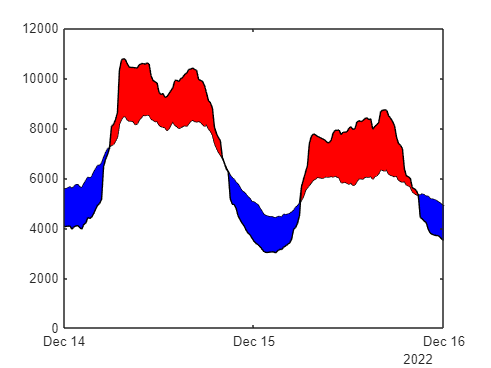

clf
area(AG.MTU,[noPHS_MW AG.PHSgen -AG.PHSpump])
% hold on
% plot(AG.MTU,(noPHS_MW+AG.PHSgen-AG.PHSpump),'black')
% plot(AG.MTU,(noPHS_MW),'red')
colororder(["w","r","b"])
% xlim([datetime(2022,12,11,16,00,00)...
%       datetime(2022,12,19,8,00,00)])
% ylim([41478 88183])

xlim([datetime(2022,12,14,0,00,00)...
      datetime(2022,12,16,0,00,00)])

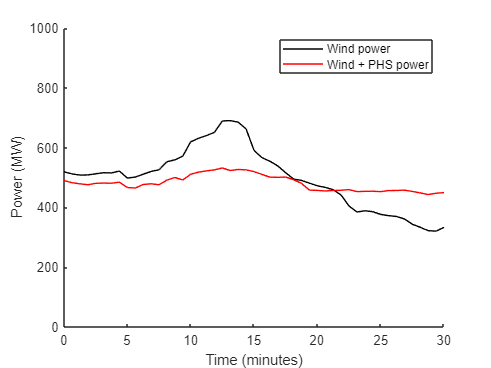

clf
% area(AG.MTU,[noPHS_MW AG.PHSgen -AG.PHSpump])
hold on
plot(AG.MTU,(noPHS_MW+AG.PHSgen-AG.PHSpump),'black')
plot(AG.MTU,(noPHS_MW),'red')
xlim([datetime(2022,10,14,12,00,00)...
      datetime(2022,10,15,0,00,00)])
xticklabels(0:5:30)
ylim([0 10000])
yticks([0:2000:12000])
yticklabels([0:200:1200])
ylabel("Power (MW)")
xlabel("Time (minutes)")
legend("Wind power","Wind + PHS power")